# SNW_V_PLANNER Planner Value More Dense Test

This is the example vignette for function: [**snw_v_planner**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/splanner/snw_v_planner.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**.** This solves the planner's problem with various checks. The planner considers unemployed and employed states and observes previous age, child count, marriage status and income level.

## Step 1: Set Parameters

Set checks and other key parameters:

% Set Parameters
mp_params = snw_mp_param('default_moredense');
mp_params('n_welfchecksgrid') = 51;
n_incgrid=201; % Number of income groups
n_incgrid_aux=round(0.75*n_incgrid);
inc_grid1=linspace(0,4,n_incgrid_aux)'; % 4 refers to 4*58056=232224 dollars in 2012USD
inc_grid=[inc_grid1;linspace(4+((7-4)/(n_incgrid-n_incgrid_aux)),7,n_incgrid-n_incgrid_aux)']; % 7 refers to 7*58056=406392 dollars in 2012USD
mp_params('n_incgrid') = n_incgrid;
mp_params('inc_grid') = inc_grid; % 7 refers to 7*58056=406392 dollars in 2012USD    

Set Controls:

mp_controls = snw_mp_control('default_test');
mp_controls('bl_timer') = true;
mp_controls('bl_print_ds') = false;
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_a4chk') = false;
mp_controls('bl_print_vu_vw') = false;
mp_controls('bl_print_ds_verbose') = false;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_print_a4chk_verbose') = false;
mp_controls('bl_print_vu_vw_verbose') = false;
mp_controls('bl_print_v_planner') = true;
mp_controls('bl_print_v_planner_verbose') = false;                                                                                                         

## Step 2: Solve the Checks Problem (Includes VFI)

% Solve At all Checks
st_solu_type = 'bisec_vec';
[~, ap_ss, cons_ss, ~, ~, ~, ...
    V_W_allchecks, C_W_allchecks, V_U_allchecks, C_U_allchecks] = snw_vu_vw_checks(st_solu_type, mp_params, mp_controls);

Elapsed time is 116.590398 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
Elapsed time is 132.574890 seconds.
Completed SNW_VFI_MAIN 1 PERIOD UNEMP SHK;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
Elapsed time is 37.442381 seconds.
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=0;TR=0.0017225;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
Elapsed time is 37.858844 seconds.
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=1;TR=0.0017225;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
Elapsed time is 37.817923 seconds.
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=2;TR=0.0017225;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
Elapsed time is 37.907669 seconds.
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=3;TR=0.0017225;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
Elapsed time is 37.856557 seconds.
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=4;TR=0.0017225;SNW_MP_PARAM=default_moredens

## Step 3: Solve for the Distribution

[Phi_true,~,~,~,~,~] = snw_ds_main(mp_params, mp_controls, ap_ss, cons_ss);

Elapsed time is 107.758933 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
Elapsed time is 278.726938 seconds.
Completed SNW_DS_MAIN;SNW_MP_PARAM=;default_moredense;SNW_MP_CONTROL=;default_test


## Step 4: Solve for Planner Value

% Solve the Planning Problem
[V_planner, C_planner, Phi_mass, output] ...
    = snw_v_planner(mp_params, mp_controls, ...
    Phi_true, ap_ss, V_W_allchecks, C_W_allchecks, V_U_allchecks, C_U_allchecks);

Wage quintile cutoffs=0.57062     0.88197      1.1634      1.7371
SNW_V_PLANNER: pre-computed incomes , time-cost:297.8251
SNW_V_PLANNER: c(1) or v(2):1
SNW_V_PLANNER: Finished Age Group:1 of 82, time-this-age:0.62029
SNW_V_PLANNER: Finished Age Group:2 of 82, time-this-age:6.9994
SNW_V_PLANNER: Finished Age Group:3 of 82, time-this-age:9.6453
SNW_V_PLANNER: Finished Age Group:4 of 82, time-this-age:11.4445
SNW_V_PLANNER: Finished Age Group:5 of 82, time-this-age:13.1759
SNW_V_PLANNER: Finished Age Group:6 of 82, time-this-age:14.641
SNW_V_PLANNER: Finished Age Group:7 of 82, time-this-age:15.9988
SNW_V_PLANNER: Finished Age Group:8 of 82, time-this-age:17.3607
SNW_V_PLANNER: Finished Age Group:9 of 82, time-this-age:18.6275
SNW_V_PLANNER: Finished Age Group:10 of 82, time-this-age:19.9073
SNW_V_PLANNER: Finished Age Group:11 of 82, time-this-age:21.0667
SNW_V_PLANNER: Finished Age Group:12 of 82, time-this-age:22.0956
SNW_V_PLANNER: Finished Age Group:13 of 82, time-this-age:23.0264
S

## Step 5: Save Outputs

Save outputs, but only where column 7, where phi_mass is stored, is not zero, do not need to store zero mass elements. At these elements, there are no V_planner or C_planner values.

output_pos_Phi_mass = output(output(:,6) ~= 0,:);
mp_path = snw_mp_path('fan');
snm_file_csv = 'snwx_v_planner_densemore.csv';
writematrix(output_pos_Phi_mass, [mp_path('spt_simu_outputs') snm_file_csv]);

## A. Distributional Mass Along Various Dimensions

*Phi_mass* has four dimensions: age, marriage status, kids, income groups

% Grids:
age_grid = 18:99;
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
inc_grid = mp_params('inc_grid')*58056;
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'kids', kids_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'ylower', inc_grid});

#### A1. Age, Marriage Status and Kids Count

These mass are the same as under ds_main analysis files, mass by age, marriage and kids count has not changed.

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [4,1,3,2];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_mass, true, ["sum"], 1, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_18    sum_age_19    sum_age_20    sum_age_21    sum_age_22    sum_age_23    sum_age_24    sum_age_25    sum_age_26    sum_age_27    sum_age_28    sum_age_29    sum_age_30    sum_age_31    sum_age_32    sum_age_33    sum_age_34    sum_age_35    sum_age_36    sum_age_37    sum_age_38    sum_age_39    sum_age_40    sum_age_41    sum_age_42    sum_age_43    sum_age_44    sum_age_45

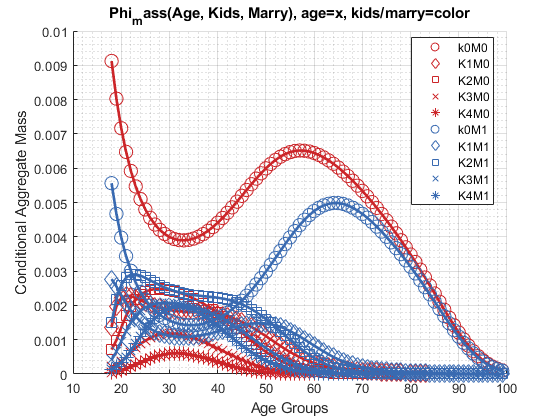

mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log
mp_support_graph('cl_st_graph_title') = {'Phi_mass(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### A2. Y Mass by Age

% NaN(n_jgrid-1,n_marriedgrid,n_kidsgrid,n_incgrid);
ar_permute = [2,3,1,4];
% Value Function
tb_prob_aage = ff_summ_nd_array("P(A,Z))", Phi_mass, true, ["sum"], 2, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group      ylower      sum_age_18    sum_age_19    sum_age_20    sum_age_21    sum_age_22    sum_age_23    sum_age_24    sum_age_25    sum_age_26    sum_age_27    sum_age_28    sum_age_29    sum_age_30    sum_age_31    sum_age_32    sum_age_33    sum_age_34    sum_age_35    sum_age_36    sum_age_37    sum_age_38    sum_age_39    sum_age_40    sum_age_41    sum_age_42    sum_age_43    sum_age_44    sum_age_45    sum_age_46  

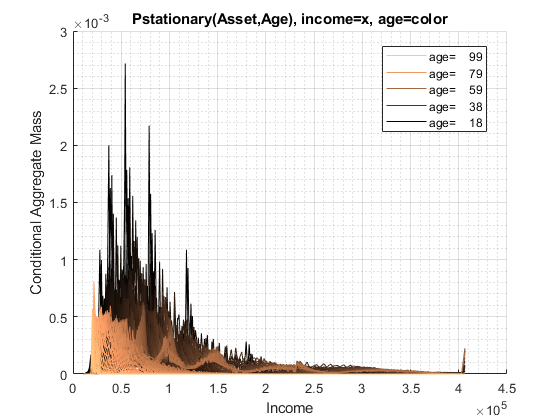

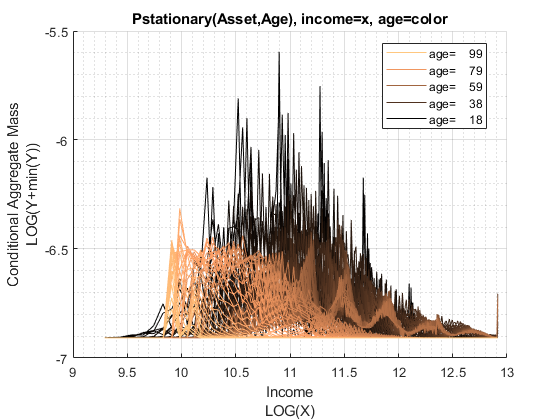

mp_support_graph('cl_st_graph_title') = {'Pstationary(Asset,Age), income=x, age=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'Income'};
mp_support_graph('st_rowvar_name') = 'age=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.0f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
% select only positive income, ignore 0 mass income levels (initial)
mt_prob_aage = tb_prob_aage{1:end, 3:end}';
it_inc_start_idx = find((sum(mt_prob_aage, 1)==0)==0);
mt_prob_aage_skipinitzrs = mt_prob_aage(:,it_inc_start_idx:end);
inc_grid_skipinitzrs = inc_grid(it_inc_start_idx:end);
ff_graph_grid(mt_prob_aage_skipinitzrs, age_grid, inc_grid_skipinitzrs, mp_support_graph);

## B. Analyze Value Among Checks

*V_planner* are values associated with different checks for different IRS observable types:

#### B1. Differences in Values Between Checks

% Grids:
cl_mp_datasetdesc_vdiff = {};
ar_diff_chk_grid = 1:1:(mp_params('n_welfchecksgrid')-1);
cl_mp_datasetdesc_vdiff{1} = containers.Map({'name', 'labval'}, {'DiffChk', ar_diff_chk_grid});
cl_mp_datasetdesc_vdiff{2} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc_vdiff{3} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc_vdiff{4} = containers.Map({'name', 'labval'}, {'kids', kids_grid});
cl_mp_datasetdesc_vdiff{5} = containers.Map({'name', 'labval'}, {'ylower', 1:length(inc_grid)});

Difference the Value Associated by type (age, marry, kids, inc) between checks

% NaN(n_jgrid-1,n_marriedgrid,n_kidsgrid,n_welfchecksgrid,n_incgrid)
mn_v_planner_chk1st = permute(V_planner, [4,1,2,3,5]);
disp(size(mn_v_planner_chk1st));

    51    82     2     5   201



% Difference between checks
mn_v_planner_chk1st_diff = diff(mn_v_planner_chk1st, 1, 1);
disp(size(mn_v_planner_chk1st_diff));

    50    82     2     5   201



% Summarize All Checks Over all Other Dimensions
ar_permute = [2,3,4,5,1];
tb_prob_aage = ff_summ_nd_array("DiffV(checks))", mn_v_planner_chk1st_diff, true, ["sum"], 4, 0, cl_mp_datasetdesc_vdiff, ar_permute);

xxx  DiffV(checks))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    DiffChk     sum        mean          std       coefvari    min      max  
    _____    _______    ______    _________    _________    ________    ___    _______

      1         1       323.58    0.0019632    0.0096492    0.20346      0      0.4174
      2         2       321.49    0.0019506    0.0094502     0.2064      0     0.40468
      3         3       320.22    0.0019429    0.0093324    0.20819      0     0.39868
      4         4       317.18    0.0019244    0.0090586    0.21244      0      0.3854
      5         5       317.07    0.0019237    0.0090529     0.2125      0     0.38532
      6         6       314.36    0.0019073    0.0088231    0.21617  

#### B2. Differences in Values Between Checks, Age, Marriage Status and Kids Count

In the exercise here, ignoring the magnitude of positive distributional mass, look at each age, education and kids group, average over all income levels (ignoring the magnitude of positive mass), and also averaging over check values. Is the marginal value gain from check higher for married or unmarried, is it higher for more kids or less kids. Mass is considered in the sense that the income range over which each age has positive mass is different.

% NaN(n_jgrid-1,n_marriedgrid,n_kidsgrid,n_welfchecksgrid,n_incgrid)
ar_permute = [1,5,2,4,3];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("AvgDiffVCheck(Age, Kids, Marry))", mn_v_planner_chk1st_diff, true, ["mean"], 2, 1, cl_mp_datasetdesc_vdiff, ar_permute);

xxx  AvgDiffVCheck(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    mean_age_44<

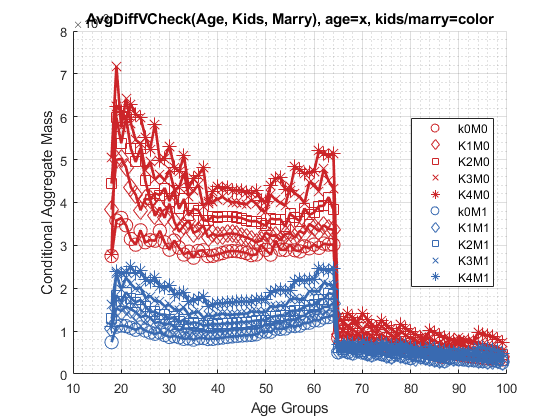

mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log
mp_support_graph('cl_st_graph_title') = {'AvgDiffVCheck(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### B3. Differences in Value By Marriage, Kids Count, and Income Levels 

Same as B2, but now average over all age, and show Y groups as the x-axis

% NaN(n_jgrid-1,n_marriedgrid,n_kidsgrid,n_welfchecksgrid,n_incgrid)
ar_permute = [1,2,5,4,3];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("AvgDiffVCheck(Income, Kids, Marry))", mn_v_planner_chk1st_diff, true, ["mean"], 2, 1, cl_mp_datasetdesc_vdiff, ar_permute);

xxx  AvgDiffVCheck(Income, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_ylower_1    mean_ylower_2    mean_ylower_3    mean_ylower_4    mean_ylower_5    mean_ylower_6    mean_ylower_7    mean_ylower_8    mean_ylower_9    mean_ylower_10    mean_ylower_11    mean_ylower_12    mean_ylower_13    mean_ylower_14    mean_ylower_15    mean_ylower_16    mean_ylower_17    mean_ylower_18    mean_ylower_19    mean_ylower_20    mean_ylower_21    mean_ylower_22    mean_ylower_23    mean_ylower_24    mean_ylowe

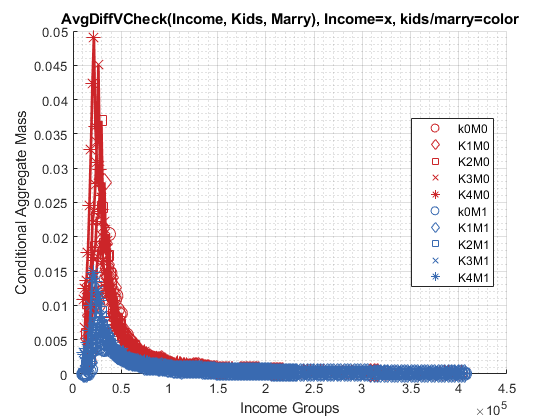

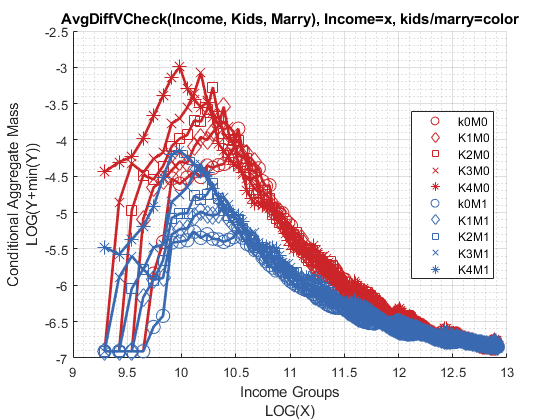

mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('cl_st_graph_title') = {'AvgDiffVCheck(Income, Kids, Marry), Income=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Income Groups'};
% select only positive income, ignore 0 mass income levels (initial)
mt_prob_amarrykids = tb_prob_amarrykids{1:end, 4:end};
it_inc_start_idx = find((sum(mt_prob_amarrykids, 1)==0)==0);
mt_prob_amarrykids_skipinitzrs = mt_prob_amarrykids(:, it_inc_start_idx:end);
inc_grid_skipinitzrs = inc_grid(it_inc_start_idx:end);
ff_graph_grid(mt_prob_amarrykids_skipinitzrs, ar_row_grid, inc_grid_skipinitzrs, mp_support_graph);